Putting together the the matrices, `A`, `B`, `Q`, `R` from the state space equations -  

clc;
clear;

% Matrix A
A = [-0.297, 0, -1, 0.0438, 0;
     0, 0, 1, 0, 0;
     0.3301, 0, -0.0042, 0, -0.0459;
     0, 0, 0, 0, 1;
     -1.1554, 0 0.1288, 0, -0.7919;];

% Matrix B
B = [0, 0;
     0, 0;
     0.3796, 0.0669;
     0, 0;
     0.3963, 0;];

% matrix Q  
Q = [1, 1, 0, 0, 0;
     1, 1, 0, 0, 0;
     0, 0, 0, 0, 0;
     0, 0, 0, 1, 0;
     0, 0, 0, 0, 0;];

% Matrix R
R = [1, 0;
     0, 1;];

% Checking for controllability 
iscontrol = rank(ctrb(A,B))

iscontrol = 5

Since the rank of controllability matrix equals number of states; the system is controllable.

% Calculating the full-state feedback gain matrix `K` using the `lqr` command 
K = lqr(A, B, Q, R);

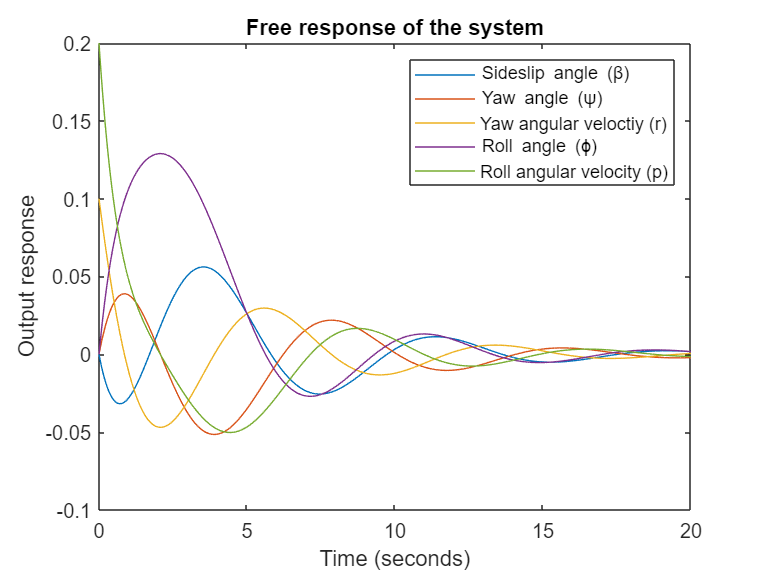

n = length(A);
C = eye(n);
D = zeros([n,2]);
tspan = 0:0.005:20; % time period is 20 seconds
x0 = [0; 0; 0.1; 0; 0.2]';
sys = ss(A-B*K,B,C,D);
[y, tspan, x] = initial(sys, x0, tspan);
figure
plot(tspan,y)
title('Free response of the system')
xlabel('Time (seconds)')
ylabel('Output response');
legend('Sideslip angle (\beta)', 'Yaw angle (\psi)', 'Yaw angular veloctiy (r)', 'Roll angle (\phi)', 'Roll angular velocity (p)', Location='northeast')